# Aula 5 - Laboratório de Controle - 2021/1

##  Efeito dos ganhos do controlador PID

## Nome: Yuri Rissi Negri

G=init(8,5)


G =
 
          121
  --------------------
  s^2 + 19.4 s + 32.46
 
Continuous-time transfer function.



Veja aqui o [Link para turmas](https://www.dropbox.com/s/iwbg4az7eg949ql/Turmas_I.pdf?dl=0).

## Atividade 1 - Avaliação do efeito do ganho proporcional Kp em regime e no transitório

Use o comando rlocus(G) ou rlocus(G,K) para obter k1 para UP=5% e k2 para UP=70%. São mostrados no LR as raízes de $1+KG(s)=0$.

Escolher Tempo de modo que na figura 1 se tenha a resposta transitória e de regime.

Execute a seção a seguir e **mostre as figuras 1 e 2 ao professor. D**epois, responda as perguntas 1.1 a 1.5.

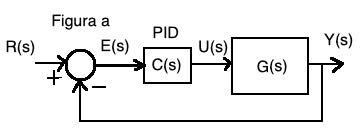

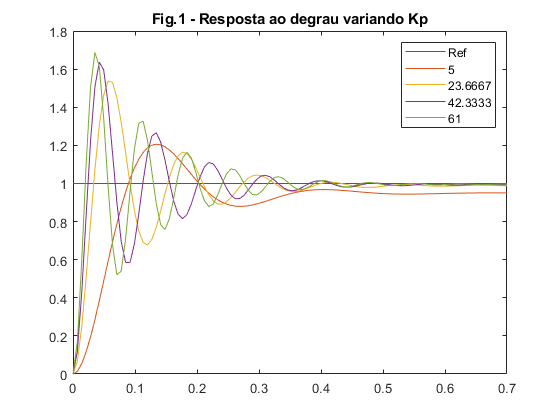

Tempo=0.7;
k1=5;
k2=61;
K=linspace(k1,k2,10);
Y=[];
C=pid(1,0,0);
t=linspace(0,Tempo,100)';
for i=1:length(K)
    C.Kp=K(i); 
    Gmf=feedback(C*G,1);
    y=step(Gmf,t); 
    S=stepinfo(y,t); 
    Erro(i,1)=100*abs(1-y(end)); 
    UP(i,1)=S.Overshoot; 
    tempo_est(i,1)=S.SettlingTime; 
    tempo_sub(i,1)=S.RiseTime;   
    IAE(i)=trapz(t,abs(1-y));
    Y=[Y y]; 
end

figure
plot(t,[ones(size(t)) Y(:,[1,4,7,10])]);title('Fig.1 - Resposta ao degrau variando Kp');
legend('Ref',num2str(K(1)),num2str(K(4)),num2str(K(7)),num2str(K(10)));

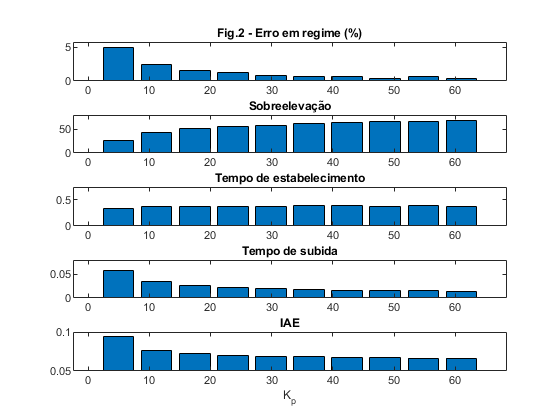


figure
subplot(5,1,1);bar(K,Erro);title('Fig.2 - Erro em regime (%)'); ylim([0 5.8])
subplot(5,1,2);bar(K,UP);title('Sobreelevação'); ylim([0 80])
subplot(5,1,3);bar(K,tempo_est);title('Tempo de estabelecimento');ylim([0 0.75])
subplot(5,1,4);bar(K,tempo_sub);title('Tempo de subida'); ylim([0 0.08])
subplot(5,1,5);bar(K,IAE);title('IAE');xlabel('K_p');ylim([0.05 0.1])

1.1 Qual o efeito do ganho Kp sobre o erro em regime?

    Conforme aumentamos o valor de Kp, nossa resposta irá apresentar um menor erro em regime permanente. 

1.2 Qual o efeito do ganho Kp sobre o tempo de subida?

    Para maiores valores de Kp, nosso sistema irá atingir 90% do seu valor de regime mais rapidamente. Podemos perceber que nosso tempo de subida será menor analisando os gráficos da figura 1.

1.3 Explique o efeito do ganho Kp sobre o tempo de estabelecimento

    Como no último laboratório, podemos perceber que o ganho Kp apresenta efeito desprezível no tempo de estabelecimento do sistema, repare na figura 1 que todas as ondas apresentam um tempo de estabelecimento muito próximo.

1.4 Qual o efeito do ganho Kp sobre a sobreelevação?

    Também observando a figura 1, fica visível que para maiores valores de Kp vamos também obter uma maior sobreelevação, que em geral, na maioria das aplicações não é um resultado desejável.

1.5 Relacione o IAE com a sobreelevação e os tempos de resposta

    Analogamente ao laboratório anterior, o tempo de subida em geral, tem um impacto maior no cálculo do IAE em relação a sobreelevação. Isso se da como explicado anteriormente pelo tempo que a onda difere do seu sinal de entrada. Por esse motivo, para maiores valores de Kp, temos um menor IAE. Contudo, como pode se observar no gráfico de barras, a diferença entre uma barra e outra se torna menor conforme aumentamos o Kp, isso se da pelo fato de que tanto o a sobrelevação quanto o tempo de subida também estão sofrendo variações pequenas.

## Atividade 2 - Avaliação do efeito do ganho integral Ki na resposta transitória e de regime

Escolha Kp_s da figura 2, de modo a ter UP=30%, aproximadamente. Execute o script abaixo para definir gaux, e obtenha o lugar das raízes em função de Ki (rlocus(gaux)) . Use o command window para fazer o rlocus, que não precisa estar no relatório. 

O LR em função de Ki plota as raízes de $1+K_i Gaux(s)=0$

kp_s=5;
den=[G.Denominator{1} 0]+[kp_s*G.Numerator{1} 0];
num=G.Numerator{1};
gaux=tf(num,den); 

Obter do LR em função de Ki o valor de kimax tal $UP\leq70%$% (aproximadamente). Verifique se a variável Tempo precisa ser ajustada para mostrar a resposta transitória e de regime.

Execute a seção a seguir e responda as perguntas 2.1 a 2.4.

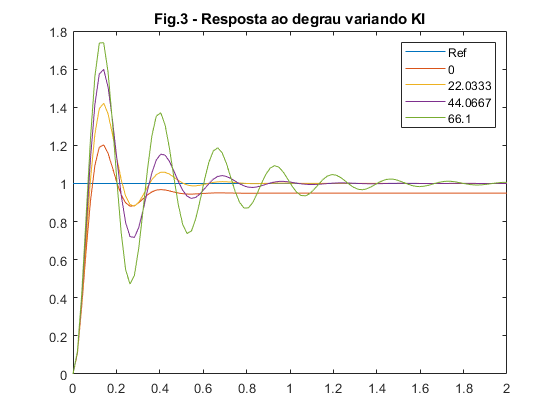

Tempo=2;
Y=[];
kimax= 66.1;
C=pid(kp_s,0,0); 
K=linspace(0,kimax,10); 
t=linspace(0,Tempo,100)'; 
for i=1:length(K)
    C.Ki=K(i); 
    Gmf=feedback(C*G,1); 
    y=step(Gmf,t); 
    S=stepinfo(y,t); 
    Erro(i,1)=100*abs(1-y(end)); 
    UP(i,1)=S.Overshoot; 
    tempo_est(i,1)=S.SettlingTime; 
    tempo_sub(i,1)=S.RiseTime;    
    IAE(i)=trapz(t,abs(1-y));
    Y=[Y y]; 
end

figure;
plot(t,[ones(size(t)) Y(:,[1,4,7,10])]);title('Fig.3 - Resposta ao degrau variando KI');
legend('Ref',num2str(K(1)),num2str(K(4)),num2str(K(7)),num2str(K(10)));

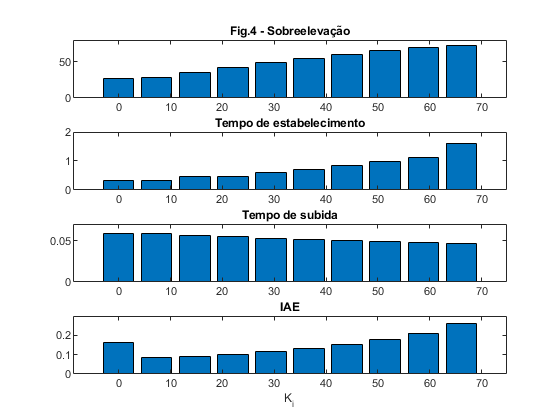


subplot(4,1,1);bar(K,UP);title('Fig.4 - Sobreelevação');ylim([0 80])
subplot(4,1,2);bar(K,tempo_est);title('Tempo de estabelecimento');ylim([0 2])
subplot(4,1,3);bar(K,tempo_sub);title('Tempo de subida');ylim([0 0.07])
subplot(4,1,4);bar(K,IAE);title('IAE');xlabel('K_i');ylim([0 0.3])

2.1 Qual o efeito do ganho Ki sobre a sobreelevação? Explique.

    Assim como Kp, o aumento de Ki vai gerar uma maior sobreelevação no nosso sistema. Fica fácil de se reparar ao olharmos para a fig 3, já que todas as curvas apresentam aproximadamente o mesmo tempo de subida, ficando bem evidente o aumento da sobreelevação com o aumento de Ki.

2.2 Qual o efeito do ganho Ki sobre a tempo de estabelecimento? Justifique

    Diferente de Kp, quando aumentamos o valor de Ki, também aumentamos o tempo de estabelecimento. Alem do gráfico de barras, podemos observar a curva com maior Ki na figura 3 e o tempo que a mesma leva para que seu valor se estabilize em regime permanente. 

2.3 Qual o efeito do ganho Ki sobre o IAE? Justifique

    Como aumentando Ki, também aumentamos da sobreelevação e do tempo de estabelecimento, que são dois parâmetros que aumentam a diferença entre a nossa curva de entrada e saída, enquanto não temos variação significativa no tempo de subida, é lógico pensar que o IAE também irá aumentar com maiores valores de Ki.

2.4 Comente o erro em regime observado, justificando

    Observando a figura 3, podemos perceber que para um valor de Ki nulo, temos que nossa curva se afasta da nossa referência. A partir do momento que temos um valor de Ki, diminuímos consideravelmente essa diferença o portanto o erro estacionário. Levando em consideração ainda que para todas as curvas temos um Kp fixo, podemos concluir que a inserção de Ki no nosso sistema diminui consideradamente nosso erro em regime permanente.

## Atividade 3 - Avaliação do efeito do ganho derivativo Kd

Escolher ki_s como sendo o valor tal que $UP\leq60$%. Escolher kdmaxcomo sendo 1 ou um pouco menor.

Execute o script abaixo e responda as perguntas 3.1 a 3.3

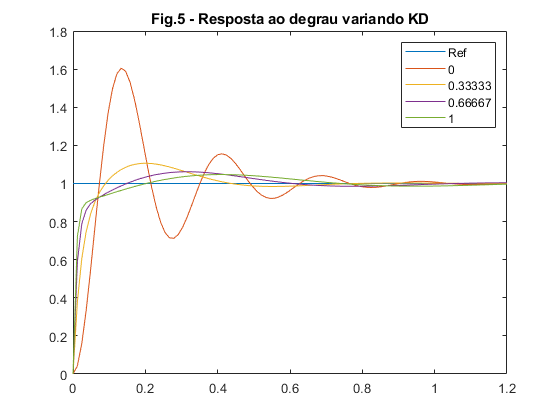

Tempo=1.2;
Y=[];
ki_s=44.07 ; 
kdmax= 1 ; 
C=pid(kp_s,ki_s,0);
K=linspace(0,kdmax,10);
t=linspace(0,Tempo,100)';

for i=1:length(K)
    C.Kd=K(i); 
    Gmf=feedback(C*G,1);
    y=step(Gmf,t);
    S=stepinfo(y,t); 
    Erro(i,1)=100*abs(1-y(end));
    UP(i,1)=S.Overshoot; 
    tempo_est(i,1)=S.SettlingTime; 
    tempo_sub(i,1)=S.RiseTime;   
    IAE(i)=trapz(t,abs(1-y));
    Y=[Y y]; 
end

figure;
plot(t,[ones(size(t)) Y(:,[1,4,7,10])]);title('Fig.5 - Resposta ao degrau variando KD');
legend('Ref',num2str(K(1)),num2str(K(4)),num2str(K(7)),num2str(K(10)));

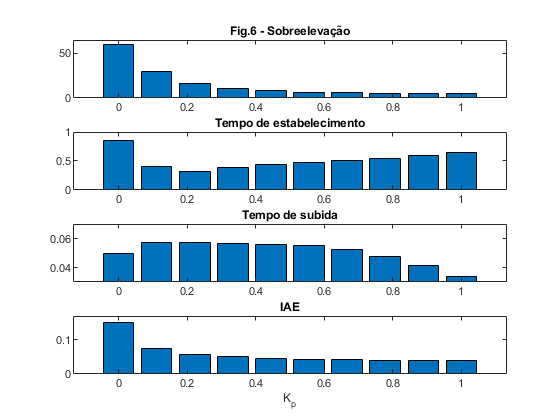


subplot(4,1,1);bar(K,UP);title('Fig.6 - Sobreelevação'); ylim([0 65])
subplot(4,1,2);bar(K,tempo_est);title('Tempo de estabelecimento'); 
subplot(4,1,3);bar(K,tempo_sub);title('Tempo de subida'); ylim([0.03 0.07])
subplot(4,1,4);bar(K,IAE);title('IAE');xlabel('K_p'); ylim([0 0.17])

3.1 Qual o efeito do ganho Kd sobre a sobreelevação? Explique.

    Podemos observar que assim como a inserção de um Ki no sistema diminui o erro estacionário, somente a inserção de um valor Kd no sistema já diminui consideravelmente a nossa sobreelevação, e conforme vamos aumentando esse ganho, diminuímos ainda mais a sobreelevação.

3.2 Qual o efeito do ganho Kd sobre o tempo de subida? Justifique

    Ao observar a figura 5, podemos perceber que com o aumento de Kd temos um tempo de subida ligeiramente menor. Contudo o aumento de Kd também gera um maior tempo de estabelecimento fazendo com que o nosso sistema se torne mais "lento". Vale a pena destacar também que com a diminuição do tempo de subida, nossa curva deixa de ser suave. 

3.3 O Kd afeta o IAE? Como?

    O Kd diminui a sobreelevação e a oscilação do sistema, o que fica evidente ao analisarmos a figura 5. Como ambos são parâmetros que aumentam o IAE, ao inserimos um Kd no nosso sistema, também terermos uma redução no IAE, e para maiores valores de Kd esses parâmetros são ainda mais atenuados. O ganho Kd também altera o tempo de subida e estabelecimento, mas em comparação com os parâmetros citados, sofrem uma variação muito menor e consequentemente tem um efeito menor no valor do IAE. 

## Atividade 4 - Seleção dos parâmetros do controlador PID

4.1 Baseado nas atividades e figuras mostradas, escolha os ganhos do controlador PID que dêem uma boa resposta, mostrando os ganhos e a resposta ao degrau correspondente. Justifique a escolha.

C=pid(5,44,0.44);

 Os valores de Kp e Ki foram definidos ao longo do programa, são os mesmos valores selecionados para kp_s e ki_s. Os valores de Kd gerados na parte 3 do laboratório, são para esses valores de Kp e Ki fixados. Assim, o primeiro valor de Kp foi selecionado pensando em atingir uma resposta com um baixo tempo de subida, Ki selecionado para obter um pequeno erro estacionário, e por fim analisando os possíveis valores de Kd, o valor selecionado foi pensando em se obter uma redução considerável na sobreelevação, mas sem deixar o sistema muito lento (aumento do tempo de estabelecimento). 

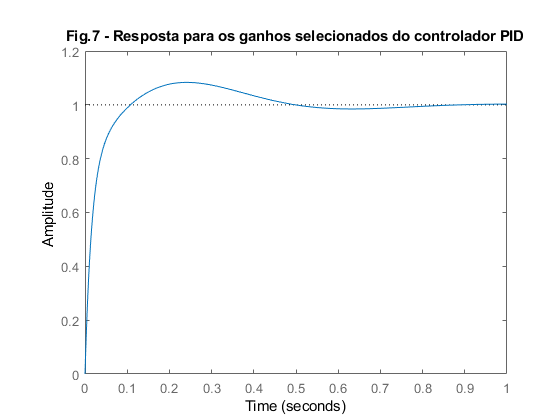

M=feedback(C*G,1);
figure;step(M);
title('Fig.7 - Resposta para os ganhos selecionados do controlador PID');

4.2 O script abaixo mostra o sinal de controle aplicado na atividade 4.1. Comente a necessidade de definir C.Tf e o valor máximo assumido pelo sinal de controle.

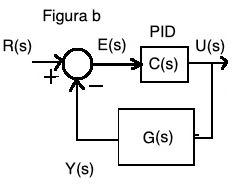

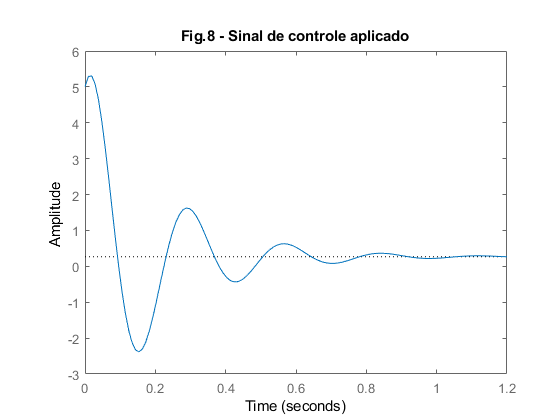

C.Tf=100;
Mru=feedback(C,G);
figure;step(Mru);title('Fig.8 - Sinal de controle aplicado')


datetime('now')

ans = datetime
   16-Jul-2021 23:48:26


pwd

ans = 'C:\Users\asus1\Desktop\Aula 5'